% Filenames
filenames1 = {'02-25-2016_22_44_18'
'02-25-2016_22_43_28'
'02-25-2016_22_42_37'
'02-25-2016_22_41_47'
'02-25-2016_22_40_56'
'02-25-2016_22_35_46'
'02-25-2016_22_34_55'
'02-25-2016_22_34_04'
'02-25-2016_22_33_14'
'02-25-2016_22_32_23'
'02-25-2016_22_31_32'
'02-25-2016_22_29_22'
'02-25-2016_22_28_31'
'02-25-2016_22_27_21'
'02-25-2016_22_26_31'
'02-25-2016_22_25_40'
'02-25-2016_22_24_20'
'02-25-2016_22_23_30'}; % 152 300 70 70 15
filenames2 = {'02-25-2016_23_09_56'
'02-25-2016_23_09_06'
'02-25-2016_23_02_47'
'02-25-2016_23_01_56'
'02-25-2016_23_01_05'
'02-25-2016_23_00_14'
'02-25-2016_22_59_24'
'02-25-2016_22_58_33'
'02-25-2016_22_57_42'
'02-25-2016_22_56_52'
'02-25-2016_22_56_01'
'02-25-2016_22_55_10'}; % 
filenames3={'02-25-2016_23_39_20'
'02-25-2016_23_38_29'
'02-25-2016_23_37_39'
'02-25-2016_23_36_48'
'02-25-2016_23_35_57'
'02-25-2016_23_35_06'
'02-25-2016_23_34_16'
'02-25-2016_23_33_25'
'02-25-2016_23_32_35'
'02-25-2016_23_29_29'
'02-25-2016_23_28_38'
'02-25-2016_23_27_48'
'02-25-2016_23_26_57'
'02-25-2016_23_26_06'
'02-25-2016_23_25_16'
'02-25-2016_23_24_25'
'02-25-2016_23_17_52'
'02-25-2016_23_17_01'
'02-25-2016_23_16_10'
'02-25-2016_23_14_53'
'02-25-2016_23_14_02'
'02-25-2016_23_13_11'
'02-25-2016_23_12_21'
'02-25-2016_23_11_30'}; % 

filenames = filenames3;


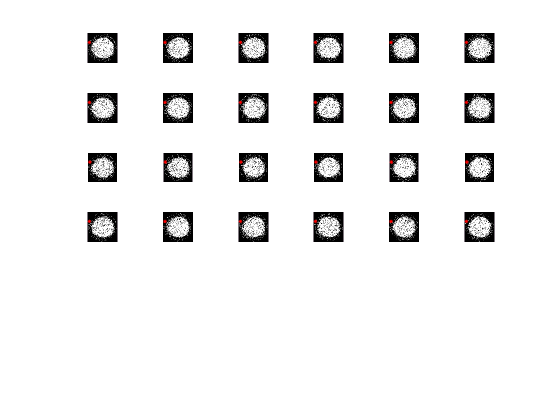

% Load data
data = cell(size(filenames));
atomno = zeros(size(data));
for i = 1:length(data)
    data{i} = imagedata(filenames{i},'crop',{'ellipse',152,300,70,70},'bg',{'avg',15},'plot',{0},'Nsat',3760*5/10);
    atomno(i) = sum(sum(getfield(data{i},'od2')));
end

%% Visualize data
figure;
for i = 1:min(6^2,length(filenames))
    subplot(6,6,i);
    imshow(getfield(data{i},'od2'),[0 1.5]); set(gca,'YDir','normal');
end


clearvars i ans

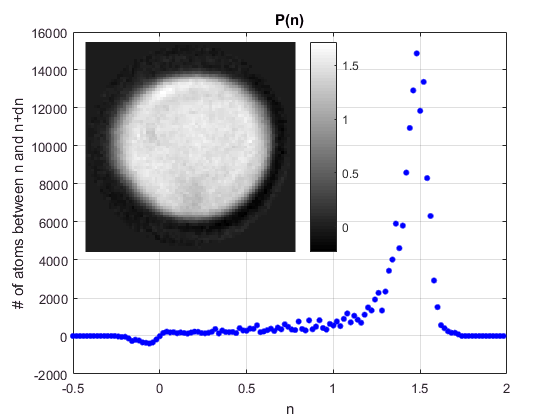

%% P(n) of average
% average_od = getfield(data{1},'od2');
average_od = imresize(getfield(data{1},'od2'),1/2);
% for i = 2:length(data), average_od = average_od + getfield(data{i},'od2'); end
for i = 2:length(data), average_od = average_od + imresize(getfield(data{i},'od2'),1/2); end
average_od = average_od / length(data);
dn_i = 0.02;
n_i_edges = (-0.5:dn_i:2)' - dn_i/2;
[n_i,P_n] = extract_Pn(average_od,'plot',1,'plot_nxy_pos',[0.15 0.4 0.5 0.5],'n_i',n_i_edges);

clearvars i dn_i

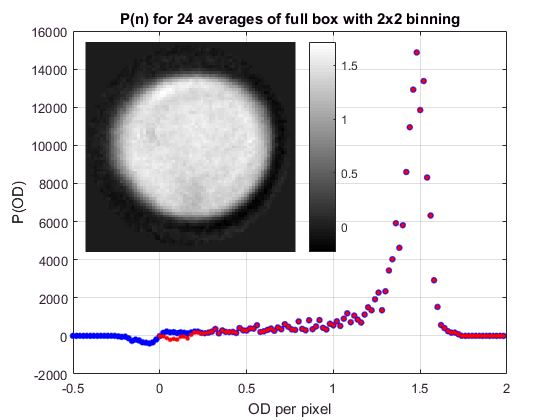

% Folding
ind = find(n_i > -1e-15,1);
P_n_bg = P_n; P_n_bg(ind+1:2*ind-1) = P_n(ind+1:2*ind-1) + flipud(P_n(1:ind-1));
figure;
plot(n_i,P_n,'b.','MarkerSize',15); hold on;
plot(n_i(ind:end),P_n_bg(ind:end),'r.','MarkerSize',10); 
grid on; title('P(n) for 24 averages of full box with 2x2 binning'); xlabel('OD per pixel'); ylabel('P(OD)');  hold off; %  legend({'P(n)','flipped'});
axes('Position',[0.15 0.4 0.5 0.5]); imagesc(average_od); axis off; axis image; colormap gray; colorbar; 

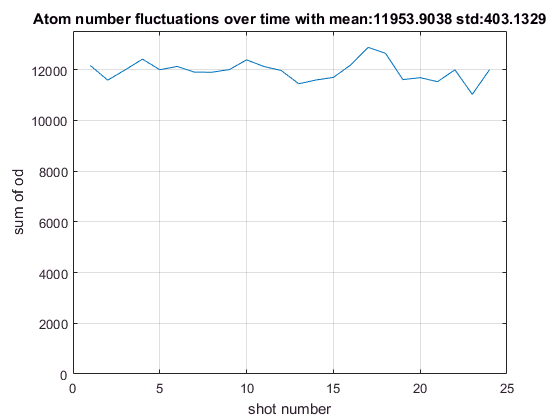

%% Atom number fluctuations
figure; plot(atomno); ylim([0,1.05*max(atomno)]);
grid on; xlabel('shot number'); ylabel('sum of od'); title(['Atom number fluctuations over time with mean:',num2str(mean(atomno)),' std:',num2str(std(atomno))]);

%% 90% atoms within 5% of peak density
% P_n_norm = P_n / sum(P_n);
% range = 10;
% [~,index] = max(P_n);
% peak_frac = sum(P_n_norm(index-range:index+range))
% peak_n = n_i(index);
% range_n = n_i(index+range) - n_i(index)
% (range_n)/peak_n*100

P_n_norm = P_n / sum(P_n);
% P_n_norm = P_n / sum(P_n( find(n_i>0.25,1) :end));
[peak_P,index] = max(P_n_norm);
expect_n = sum(n_i.*P_n_norm);
% peak_n = n_i(index);
peak_n = expect_n

peak_n = 1.3677

percent = 0.1;
index_min = find(n_i >= peak_n * (1-percent),1);
index_max = find(n_i > peak_n * (1+percent),1); 
peak_atoms = sum(P_n_norm(index_min:index_max))*100;
disp([num2str(peak_atoms),'% of atoms are within +- ',num2str(percent*100),'% of peak density']);

69.7611% of atoms are within +- 10% of peak density


%% Plots
figure;
plot(n_i2,P_n2,'b-','MarkerSize',10); hold on;

Undefined function or variable 'n_i2'.


plot(n_i5,P_n5,'r-','MarkerSize',10);
% plot(n_i10,P_n10,'k--','MarkerSize',10);
plot(n_i18,P_n18,'k-','MarkerSize',10);
legend({'2 images','5 images','18 images'});
grid on; title('P(n) full box with small aperture'); xlabel('OD per pixel'); ylabel('P(OD)'); hold off; 
